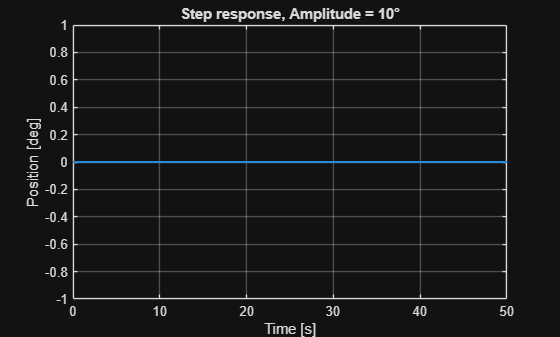

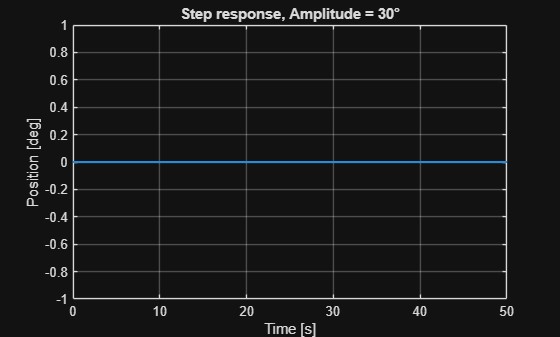

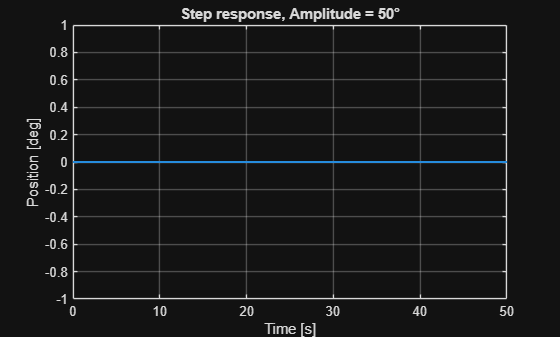

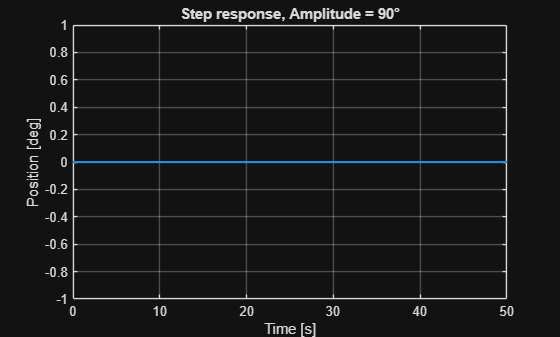

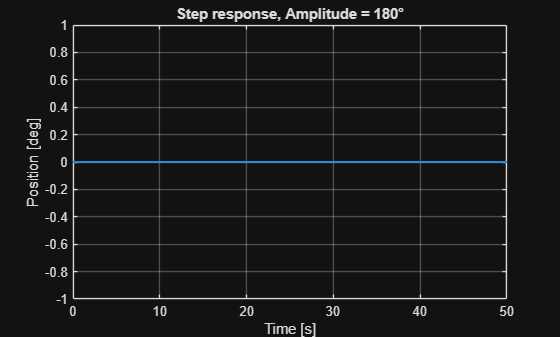

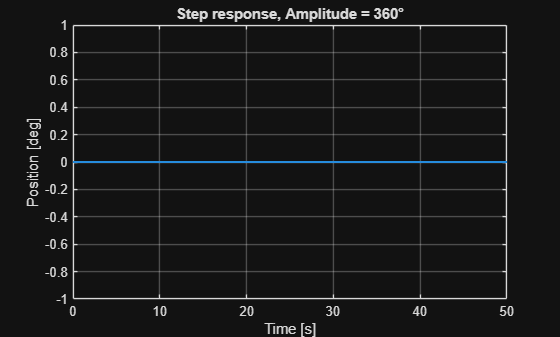

% Verification of the step response using simulink Black_box_system.slx
% Black_box_system.slx contains the model required at point 3.1 in the Laboratory
% assignments. Steps amplitude: 10° 30° 50° 90° 180° 360°. This model will
% run on the real motor in lab.


clc
load('parameters.mat')


% Select the correct input: step with variable gain

simul.select1 = 1;
simul.select2 = 2;
simul.stair_gain = 1;

% Define the amplitude vector
step_amplitudes_real = [10, 30, 50, 90, 180, 360];

for i = 1:length(step_amplitudes_real)

    step_gain = step_amplitudes_real(i);
    sim_step_real = sim('Real_system.slx');

    % Create plots
    figure; 
    plot(sim_step_real.th, 'LineWidth', 1.5);
    grid on;
    title(sprintf('Step response, Amplitude = %d°', step_gain));
    xlabel('Time [s]');
    ylabel('Position [deg]');
    
    % Save data and plots (optional)

    % save data
    % base_name = sprintf('step_response_%d', step_gain);
    % save([base_name, '.mat'], 'simOut');
    
    % save the plots
    % saveas(gcf, [base_name, '.png']);
    drawnow; 
end